#      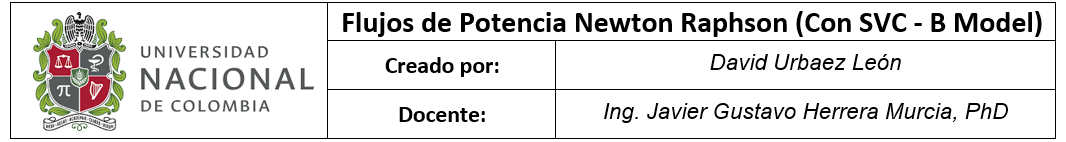

### 1)    Se definen las bases del sistema

-  Potencia base $S_b ={100\cdot 10}^{6\;}$[VA]

-  Voltaje base   $V_b ={230\cdot 10}^{3\;}$[V]

Sb = 100e6; %[VA]
Vb = 230e3; %[V]

### 2)    Se crean las matrices  con la información de la red ( br_data, N_data ):

Se deben crear dos matrices para ingresar la información referente al circuito. La primera (br_data) brinda información acerca de las conexiones entre buses como la impedancia de la línea o los buses entre los cuales se realiza la conexión , mientras que la segunda (N_data) da información acerca de la naturaleza de cada uno de los buses, tipo de bus (SL, PV o PQ).

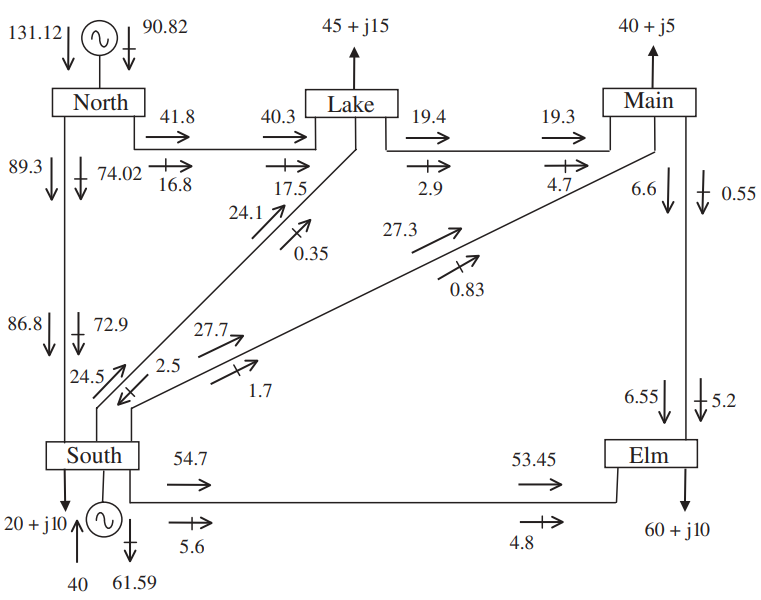

a) Para la matriz **br_data** se tiene que el formato es

                    
$$\mathrm{br}_\mathrm{data}=\left\lbrack {\mathrm{Bus}}_{\mathrm{from}\;} ,{\mathrm{Bus}}_{\mathrm{to}} ,R,X,G,B\right\rbrack \;\mathrm{in}\;p\ldotp u\ldotp$$


b) Para la matriz **N_data **se tiene que el formato es:

                  
$$N_‾‾\mathrm{data}=\left\lbrace \mathrm{#Bus},\mathrm{type}\left(\prime \mathrm{SL}\prime ,\prime \mathrm{PQ}\prime ,\prime \mathrm{PV}\prime \right),V\left\lbrack p\ldotp u\ldotp \right\rbrack ,\angle \mathrm{Vº},\mathrm{PG}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{QG}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{PL}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{QL}\left\lbrack p\ldotp u\ldotp \right\rbrack \right\rbrace$$


% Branches data R, X, G, B
% Types: General in form of impedance. (G & B are split in half at both ends).

% br_data=[ bus1, bus2,     R,     X,     G,      B] in p.u.
br_data = [
            1,      2,  0.02,    0.06,    0.0,    0.06;
            1,      3,  0.08,    0.24,    0.0,    0.05;
            2,      3,  0.06,    0.18,    0.0,    0.04;
            2,      4,  0.06,    0.18,    0.0,    0.04;
            2,      5,  0.04,    0.12,    0.0,    0.03;
            3,      4,  0.01,    0.03,    0.0,    0.02;
            4,      5,  0.08,    0.24,    0.0,    0.05];

% Node definitions
% {  #, type,   Vpu,    <Vº,   PG pu,  QG pu,  PL pu, QL pu}
N_data = {
    1,  'SL',   1.06,   0.0,    0.0,    0.0,    0.00,    0.00;
    2,  'PV',   1.0,    0.0,    0.4,    0.0,    0.20,    0.10;
    3,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.45,    0.15;
    4,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.40,    0.05;
    5,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.60,    0.10;  };

br_data=array2table(br_data,'VariableNames',{'FromBus','ToBus','R','X','G','B'});
N_data=cell2table(N_data,'VariableNames',{'n','type','Vm','Va','PG','QG','PL','QL'});

c) Para el SVC:

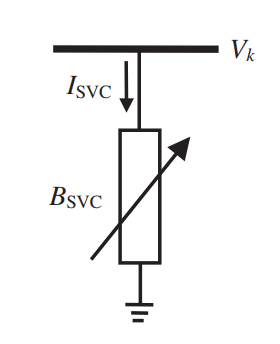

% VARIABLE SHUNT SUSCEPTANCE MODEL

% SVCsend : Compensated bus
% B : Initial SVC’s susceptance value (p.u.)
% Bmin : Lower limit of variable susceptance (p.u.)
% Bmax : Higher limit of variable susceptance (p.u)
% TarVol : Target nodal voltage magnitude to be controlled by SVC (p.u.)
% VSta : Indicate control status for nodal voltage magnitude:1 is on and 0 is off

% SVC_data = [SVC node, SVC B, SVC Bmin, SVC Bmax, SVC TarVol, SVC Vsta]
SVC_data   = [   3   ,  0.02,    -0.25,     0.25 ,       1     ,      1];

SVC_data=array2table(SVC_data,'VariableNames',{'SVCBus','B','Bmin','Bmax','Tv','Status'})

SVC_data = 1×6 table
    SVCBus     B      Bmin     Bmax    Tv    Status
    ______    ____    _____    ____    __    ______

      3       0.02    -0.25    0.25    1       1   


SVC_target_V=0.98:0.005:1;
V_out=[];
S_out=[];
for TarVol_index=1:length(SVC_target_V)
    SVC_data.Tv = SVC_target_V(TarVol_index);


    Run_PowerFlow_SVC_B_Model
    
    %% Se guardan variables
    V_out=[V_out Vn];
    if TarVol_index==1
        S_out=[S_out S_pf];
    else
        S_out=[S_out S_pf(:,3:end)];
    end
end

##    7) Se presentan los resultados obtenidos   

El cambio en la tensión de los nodos 4 y 5 ante variaciones en la tensión establecida para el nodo 3 es:

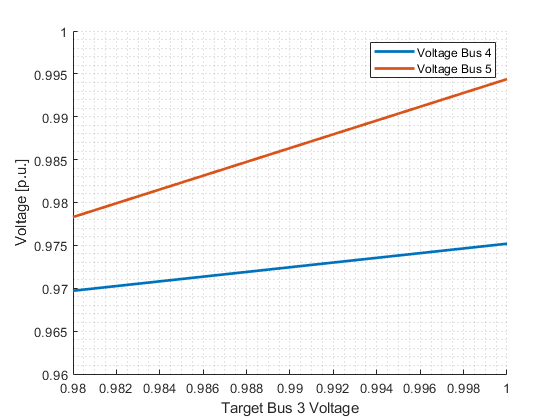

figure()
hold on; grid minor
plot(SVC_target_V,abs(V_out(5,:)),'LineWidth',2)
plot(SVC_target_V,abs(V_out(4,:)),'LineWidth',2)
xlabel('Target Bus 3 Voltage')
ylabel('Voltage [p.u.]')
legend('Voltage Bus 4','Voltage Bus 5')
xlim([0.98,1])
ylim([0.96,1])

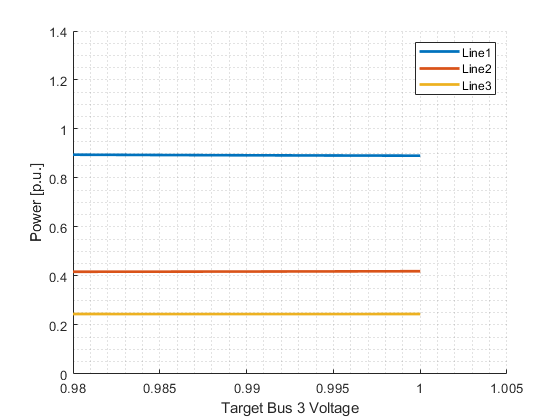

figure();
hold on; grid minor
plot(SVC_target_V,abs(S_out(1,3:3:end)),'LineWidth',2);
plot(SVC_target_V,abs(S_out(3,3:3:end)),'LineWidth',2);
plot(SVC_target_V,abs(S_out(5,3:3:end)),'LineWidth',2)
xlabel('Target Bus 3 Voltage')
ylabel('Power [p.u.]')
legend('Line1','Line2','Line3')
ylim([0,1.4])

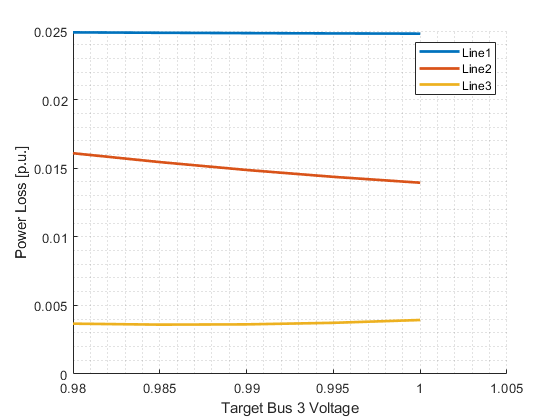


figure()
hold on; grid minor
plot(SVC_target_V,S_out(1,3:3:end)+S_out(2,3:3:end),'LineWidth',2);
plot(SVC_target_V,S_out(3,3:3:end)+S_out(4,3:3:end),'LineWidth',2);
plot(SVC_target_V,S_out(5,3:3:end)+S_out(6,3:3:end),'LineWidth',2);
xlabel('Target Bus 3 Voltage')
ylabel('Power Loss [p.u.]')
legend('Line1','Line2','Line3')

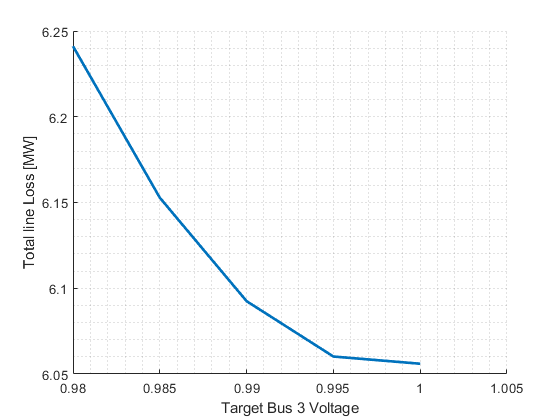

Total_line_loss=sum(S_out(1:2:end,3:3:end)+S_out(2:2:end,3:3:end));
figure()
hold on; grid minor
plot(SVC_target_V,Sb/1e6*Total_line_loss,'LineWidth',2);
xlabel('Target Bus 3 Voltage')
ylabel('Total line Loss [MW]')

### 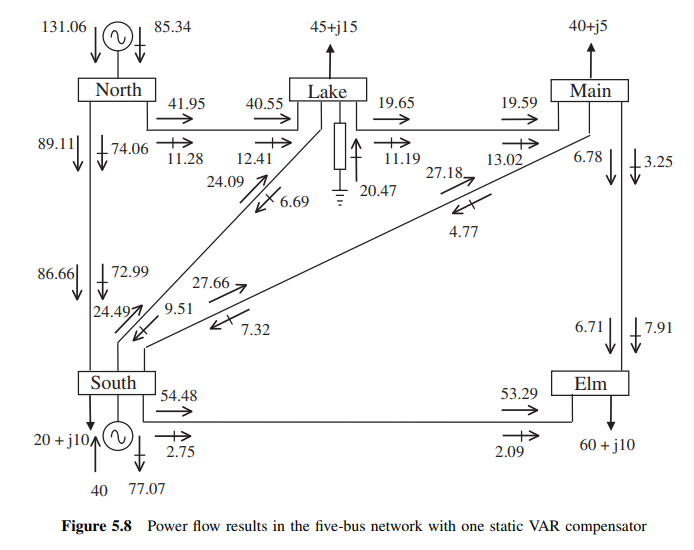

### Referencias:

[1] Gomez - Exposito,A. Electrica Energy Systems, Analysis and operation. 2nd Edition. Boca Raton : Taylor & Francis, CRC Press, 2018.

[2] Acha,E. FACTS Modelling and Simulation in Power Networks. 1st Edition. Boca Raton : John Wiley & Sons Inc,2004 